# Problem 3

Re = 6378.1; % Earth radius, km
mu = 398600.4415; % Earth mu, km^3/s^2

e = 0.65

e = 0.6500

a = 4.4*Re

a = 2.8064e+04

ths0_deg = -30, ths0 = deg2rad(ths0_deg)

ths0_deg = -30

ths0 = -0.5236

## Preliminary Calculations (Characterize Original Orbit)

p = a*(1-e^2)

p = 1.6207e+04

r0mag = p/(1+e*cos(ths0))

r0mag = 1.0370e+04

h = sqrt(mu*p)

h = 8.0374e+04

r0= r0mag*[1 0]'

r0 = 	1.0e+04 *

    1.0370
         0


v = [mu*e*sin(ths0)/h, h/r0mag]'

v =    -1.6118
    7.7510


v0mag = norm(v)

v0mag = 7.9168

gamma0 = asin(v(1)/v0mag)

gamma0 = -0.2050

gamma0_deg = rad2deg(gamma0)

gamma0_deg = -11.7469

## Part a)

E0 = 2*atan(sqrt((1-e)/(1+e))*tan(ths0/2)), E0_deg = rad2deg(E0)

E0 = -0.2456

E0_deg = -14.0704

ths1 = pi, ths1_deg = rad2deg(ths1)

ths1 = 3.1416

ths1_deg = 180

E1 = 2*atan(sqrt((1-e)/(1+e))*tan(ths1/2)), E1_deg = rad2deg(E1)

E1 = 3.1416

E1_deg = 180

dt0 = sqrt(a^3/mu) * (E0 - e*sin(E0))

dt0 = -651.9397

dt1 = sqrt(a^3/mu) * (E1 - e*sin(E1))

dt1 = 2.3394e+04

waittime = dt1 - dt0

waittime = 2.4046e+04

waittime_hr = waittime/3600

waittime_hr = 6.6793

ra = p/(1+e*cos(pi)); r1 = ra*[1 0], r1mag = norm(r1)

r1 = 	1.0e+04 *

    4.6305         0


r1mag = 4.6305e+04

rN = ra

rN = 4.6305e+04

v1mag = sqrt(mu*(2/r1mag - 1/a))

v1mag = 1.7358

v1 = v1mag*[0 1]'

v1 =          0
    1.7358


vNmag = sqrt(mu/rN)

vNmag = 2.9340

pN = rN;
aN = rN;
gamma = 0;
gammaN = acos(sqrt(mu*pN)/(rN*vNmag))

gammaN = 0

dvmag = sqrt(vNmag^2 + v1mag^2 - 2*vNmag*v1mag*cos(gammaN - gamma))

dvmag = 1.1982

vN = vNmag * [0 1]'

vN =          0
    2.9340



%% plotting

% plot original orbit

thplot = linspace(0,2*pi,2^10);
rplot = p./(1+e*cos(thplot));
rx = rplot.*cos(thplot); ry = rplot.*sin(thplot);
plot(rx,ry)
hold on
rNx = rN.*cos(thplot); rNy = rN.*sin(thplot);
plot(rNx,rNy)
axis equal
xlim(1.2*[-rN rN])
ylim(1.2*[-rN rN])
grid on
title('Circularizing Maneuver at Apogee')
xlabel('X position, km')
ylabel('Y Position, km')
plot(0,0,'go','markersize',20)
plot(-rN,0,'r*','markersize',10)
iCr = [cos(ths1) -sin(ths1); sin(ths1) cos(ths1)]

iCr =    -1.0000   -0.0000
    0.0000   -1.0000


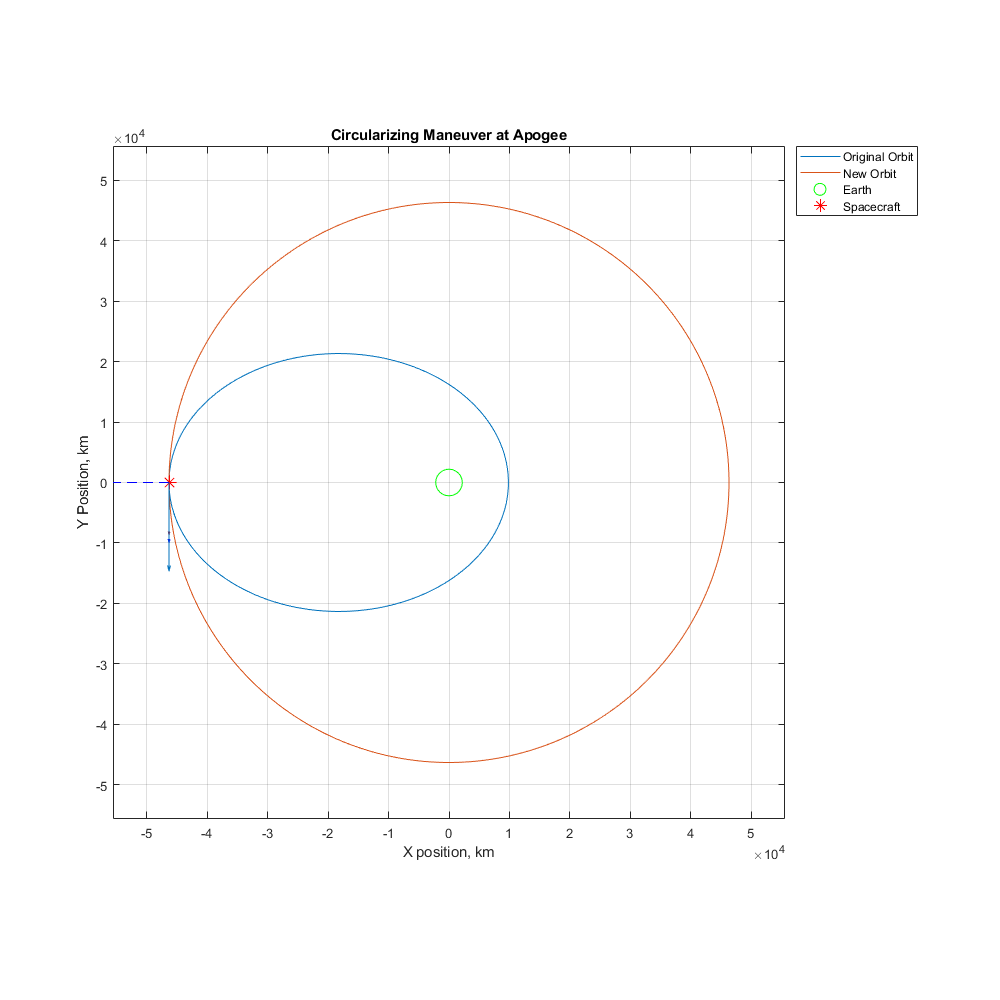

vNplot = iCr * vN;
v1plot = iCr * v1;
quiver(-rN,0,cos(ths1),sin(ths1),1e4,'b--')% r hat 
quiver(-rN,0,-sin(ths1),cos(ths1),1e4,'b--')% th hat
quiver(-rN,0,v1plot(1),v1plot(2),5e3) % v1
quiver(-rN,0,vNplot(1),vNplot(2),5e3) % vN
set(gcf,'position',[0,0,1000,1000])
legend('Original Orbit','New Orbit','Earth','Spacecraft','location','northeastoutside')

## Part b)

r2mag = 6.6*Re

r2mag = 4.2095e+04

ths2 = -acos(1/e * (p/r2mag - 1))

ths2 = -2.8119

ths2_deg = rad2deg(ths2)

ths2_deg = -161.1121

v2 = [(mu*e/sqrt(mu*p)*sin(ths2)), mu/sqrt(mu*p)*(1+e*cos(ths2))]'

v2 =    -1.0435
    1.9093


v2mag = norm(v2)

v2mag = 2.1759

gamma2 = asin(v2(1)/v2mag); gamma2 = [pi-gamma2 gamma2]; gamma2 = gamma2(2)

gamma2 = -0.5002

gamma2_deg = rad2deg(gamma2)

gamma2_deg = -28.6582

E2 = 2*atan(sqrt((1-e)/(1+e))*tan(ths2/2))+2*pi, E2_deg = rad2deg(E2)

E2 = 3.8348

E2_deg = 219.7151

dt2 = sqrt(a^3/mu) * (E2 - e*sin(E2))

dt2 = 3.1648e+04

dt2_hr = dt2/3600

dt2_hr = 8.7911

waittime2 = dt2-dt0, waittime2_hr = waittime2/3600

waittime2 = 3.2300e+04

waittime2_hr = 8.9722

vNmag = sqrt(mu/r2mag)

vNmag = 3.0772

gammaN = 0;
dvmag = sqrt(vNmag^2 + v2mag^2 - 2*vNmag*v2mag*cos(gammaN - gamma2))

dvmag = 1.5661

dv = vN - v2

dv =     1.0435
    1.0246


vN = vNmag * [0 1]'

vN =          0
    3.0772


alpha = asin(vNmag * sin(gammaN - gamma2)/dvmag)

alpha = 1.2294

alpha_deg = rad2deg(alpha)

alpha_deg = 70.4405


figure
thplot = linspace(0,2*pi,2^10);
rplot = p./(1+e*cos(thplot));
rx = rplot.*cos(thplot); ry = rplot.*sin(thplot);
plot(rx,ry)
hold on

rNx = r2mag.*cos(thplot); rNy = r2mag.*sin(thplot);
plot(rNx,rNy)
axis equal
xlim(1.2*[-rN rN])
ylim(1.2*[-rN rN])
grid on
title('Circularizing Maneuver at r = 6.6R_{e} (Descending)')
xlabel('X position, km')
ylabel('Y Position, km')
plot(0,0,'go','markersize',20)
iCr = [cos(ths2) -sin(ths2); sin(ths2) cos(ths2)]

iCr =    -0.9462    0.3237
   -0.3237   -0.9462


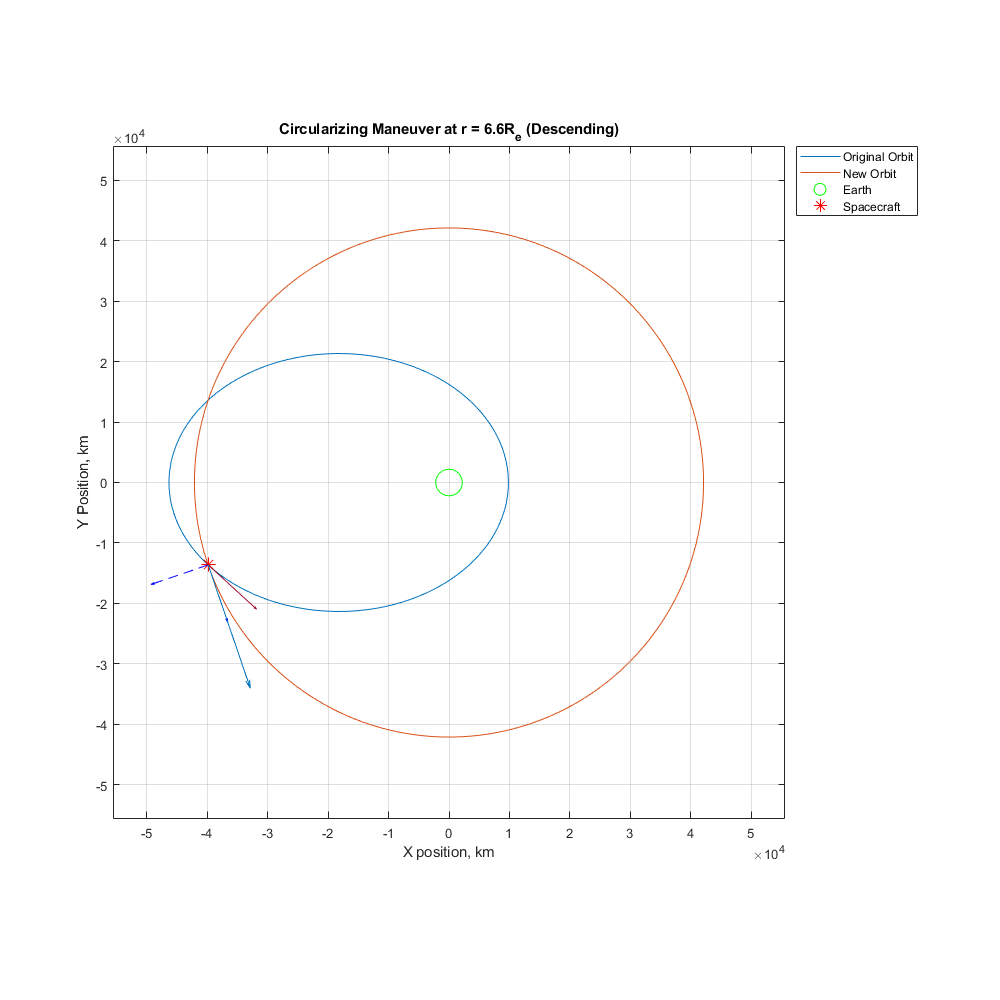

vNplot = iCr * vN;
v2plot = iCr * v2;
plot(r2mag*cos(ths2),r2mag*sin(ths2),'r*','markersize',10)
quiver(r2mag*cos(ths2),r2mag*sin(ths2),cos(ths2),sin(ths2),1e4,'b--')% r hat 
quiver(r2mag*cos(ths2),r2mag*sin(ths2),-sin(ths2),cos(ths2),1e4,'b--')% th hat
quiver(r2mag*cos(ths2),r2mag*sin(ths2),v2plot(1),v2plot(2),5e3) % v2
quiver(r2mag*cos(ths2),r2mag*sin(ths2),vNplot(1),vNplot(2),7e3) % vN
set(gcf,'position',[0,0,1000,1000])
legend('Original Orbit','New Orbit','Earth','Spacecraft','location','northeastoutside')